% Create path
clear all; close all; clc
addpath(genpath(cd)); % add all subfolders of cd to path

### Step 0: Aponeurosis depth range selection

load('parms.mat'); % start with default parameters
load('Data\example_ultrasound_image2.mat')
[n,m] = size(data); % data needs to be a n-by-m numeric array

parms.apo.super.cut(1) = 0.05; parms.apo.super.cut(2) = 0.2; 
parms.apo.deep.cut(1) = 0.3; parms.apo.deep.cut(2) = 0.5; 


### Step 1: Vessel enhancement filtering

parms.apo.frangi.FrangiScaleRange(1) = 18; parms.apo.frangi.FrangiScaleRange(2) = 20;
parms.fas.frangi.FrangiScaleRange(1) = 1; parms.fas.frangi.FrangiScaleRange(2) = 4;
parms.apo.th = 0.5; parms.apo.sigma = 10;
parms.fas.th =0.2; 

parms.apo.show = 0;
[fas_thres, super_apo, deep_apo] = filter_usimage(data,parms);
th_apo = super_apo+deep_apo; th_apo(th_apo>1) = 1;

### Step 2 & 3: Select aponeurosis objects and do Hough transform

% Define the horizontal aponeurosis spacing
apomargin = 100; apospacing = 10;
parms.apo.super.apox = apomargin:apospacing:(m-apomargin);
parms.apo.deep.apox = apomargin:apospacing:(m-apomargin);

% Hough parameters parameters
parms.fas.range(1) = 10; parms.fas.range(2) = 80; 
parms.fas.npeaks = 5;

% Show figure?
parms.show = 1;
parms.apo.show = 0;


### Run algorithm and plot figures

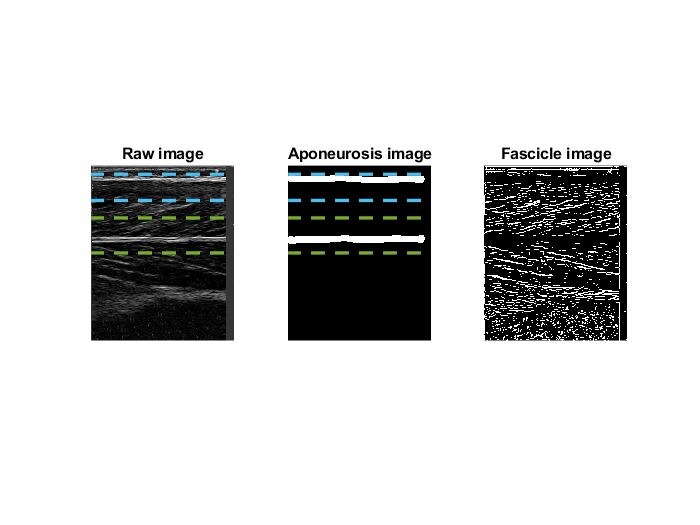

figure(1); 
subplot(131); imshow(data); title('Raw image')

subplot(132); imshow(th_apo);
color = get(gca,'colororder');

for j = 1:2
    subplot(1,3,j);
for i = 1:2
    line('xdata', [1 m] , 'ydata', n.*[parms.apo.super.cut(i) parms.apo.super.cut(i)],...
        'linewidth',2, 'linestyle', '--', 'color', color(6,:))

    line('xdata', [1 m] , 'ydata', n.*[parms.apo.deep.cut(i) parms.apo.deep.cut(i)],...
        'linewidth',2, 'linestyle', '--', 'color', color(5,:))
end
end
title('Aponeurosis image')

subplot(133); imshow(fas_thres);
title('Fascicle image')


% Run auto_ultrasound
figure;
[alpha, betha, thickness] = auto_ultrasound(data,parms);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

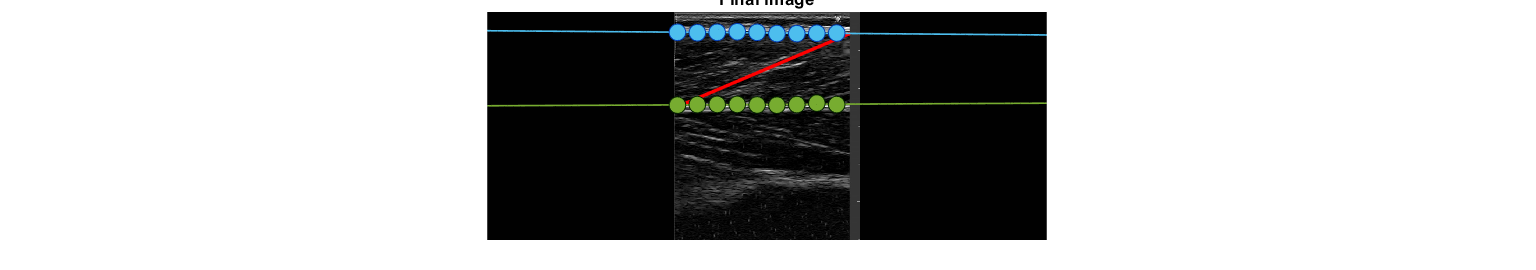

title('Final image'); set(gcf,'units','normalized','position', [.1 .3 .8 .25])

% Display things
disp(['Fascicle angle = ' , num2str(round(alpha,3)), ' deg' ]); disp(['Superficial aponeurosis angle = ' , num2str(round(betha,3)), ' deg' ]); disp(['Muscle thickness = ' , num2str(round(thickness,3)), ' pixels' ])

Fascicle angle = 23 deg
Superficial aponeurosis angle = -0.432 deg
Muscle thickness = 395.307 pixels


### Step 4: Determine fascicle length and pennation angle from trigonometry

% Pennation angle (phi) and fascicle length
phi = alpha - betha;
faslen = thickness ./ sind(phi);

% Display pennation angle and fascicle length
disp(['Pennation angle = ' , num2str(round(phi,2)), ' deg' ]); disp(['Fascicle length = ' , num2str(round(faslen,1)), ' pixels'])

Pennation angle = 23.43 deg
Fascicle length = 994.1 pixels



if exist('pixtocm','var')
    faslen_cm = faslen / pixtocm;
    disp(['Assuming ', num2str(pixtocm),' pixels per cm: ']);
    disp(['Fascicle length = ' , num2str(round(faslen_cm,2)), ' cm'])
end

Assuming 204.6 pixels per cm: 


Fascicle length = 4.86 cm
